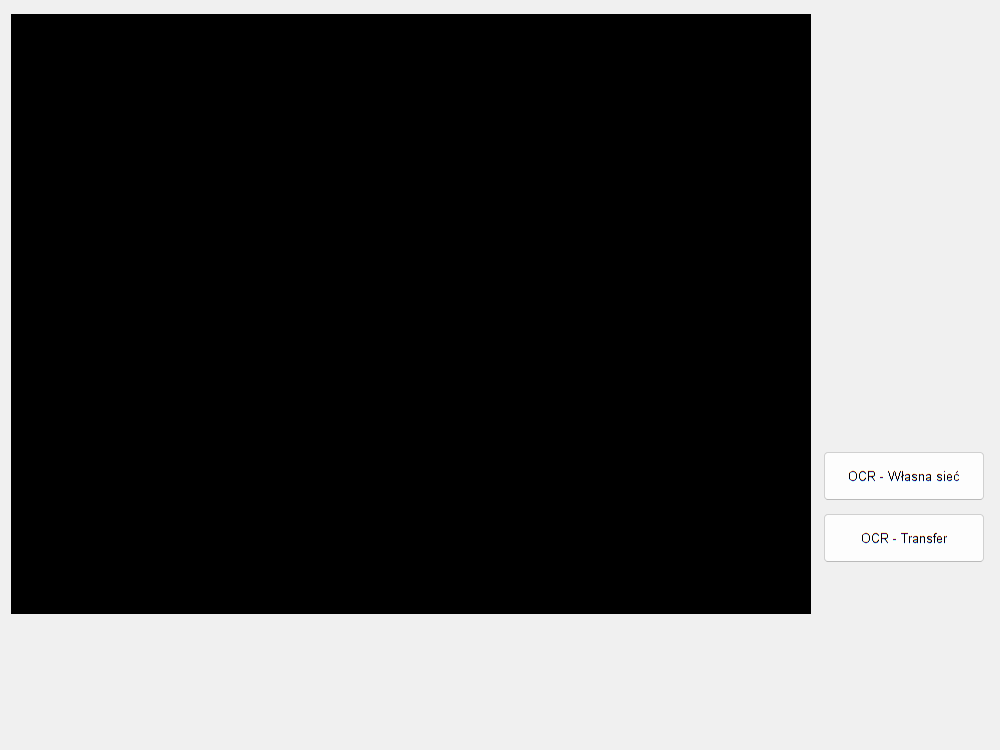

clear all;
clear rpi;

% Połączenie z Raspberry Pi
rpi = raspi('192.168.137.151', 'szymek', 'pi');
global cam imageHandle textBox;
cam = cameraboard(rpi, 'Resolution', '640x480');

% Tworzenie GUI
f = figure('Name', 'OCR z Raspberry Pi', 'NumberTitle', 'off', ...
           'MenuBar', 'none', 'ToolBar', 'none', 'Resize', 'off');
set(f, 'Position', [100, 100, 800, 600]);

% Oś do wyświetlania obrazu
ax = axes('Parent', f, 'Units', 'pixels', 'Position', [10, 110, 640, 480]);
imageHandle = imshow(zeros(480, 640, 3, 'uint8'), 'Parent', ax);

% Pole tekstowe do wyświetlania rozpoznanego tekstu
textBox = uicontrol('Parent', f, 'Style', 'text', 'String', '', ...
                    'Position', [660, 300, 130, 100], ...
                    'HorizontalAlignment', 'left', ...
                    'FontSize', 12);

% Przycisk do robienia zdjęcia i OCR - Sieć 1
btn1 = uicontrol('Parent', f, 'Style', 'pushbutton', 'String', 'OCR - Własna sieć', ...
                 'Position', [660, 200, 130, 40], ...
                 'Callback', @captureAndOCR);

% Przycisk do robienia zdjęcia i OCR - Sieć 2
btn2 = uicontrol('Parent', f, 'Style', 'pushbutton', 'String', 'OCR - Transfer', ...
                 'Position', [660, 150, 130, 40], ...
                 'Callback', @captureAndOCR_Network2);


% Strumieniowanie obrazu
while isvalid(f)
    img = snapshot(cam);
    pause(0.1);
    img = flip(img, 1);
    set(imageHandle, 'CData', img);
    drawnow;
end

Error while capturing image.

function captureAndOCR(~, ~)
    global cam imageHandle textBox;
    try
        % Pobierz obraz z kamery
        img = snapshot(cam);
        img = flip(img, 1);
        grayImg = rgb2gray(img); % Konwersja do skali szarości
        enhancedImg = imadjust(grayImg); % Automatyczna korekcja kontrastu
        binaryImg = imbinarize(enhancedImg); % Zamiana na obraz binarny
        img = medfilt2(binaryImg, [3, 3]); % Filtr medianowy

        % Wyświetl obraz
        set(imageHandle, 'CData', img);

        % Rozpoznawanie tekstu - Sieć 1
        detectedText = ocr(img);
        recognizedText = strtrim(detectedText.Text);
        set(textBox, 'String', recognizedText);

        % Synteza mowy
        if ispc
            NET.addAssembly('System.Speech');
            synth = System.Speech.Synthesis.SpeechSynthesizer;
            Speak(synth, recognizedText);
        else
            disp('Synteza mowy działa tylko na Windows za pomocą .NET');
        end
    catch ME
        disp(['Błąd: ', ME.message]);
    end
end

function captureAndOCR_Network2(~, ~)
    global cam imageHandle textBox;
    try
        % Pobierz obraz z kamery
        img = snapshot(cam);
        img = flip(img, 1);
        imwrite(img,"obrona.jpg")
        grayImg = rgb2gray(img); % Konwersja do skali szarości
        enhancedImg = imadjust(grayImg); % Automatyczna korekcja kontrastu
        binaryImg = imbinarize(enhancedImg); % Zamiana na obraz binarny
        img = medfilt2(binaryImg, [3, 3]); % Filtr medianowy

        % Wyświetl obraz
        set(imageHandle, 'CData', img);

        % Rozpoznawanie tekstu - Sieć 2 (Przykładowa implementacja innej sieci OCR)
        % Możesz tutaj wczytać własną sieć OCR (np. trenowaną w MATLAB lub innym środowisku)
        % Na potrzeby tego przykładu zakładamy, że funkcja `ocrNetwork2` zwraca wyniki OCR
        recognizedText1 = ocr(img);
        recognizedText=recognizedText1.Text
        

        % Synteza mowy
        if ispc
            NET.addAssembly('System.Speech');
            synth = System.Speech.Synthesis.SpeechSynthesizer;
            Speak(synth, recognizedText);
        else
            disp('Synteza mowy działa tylko na Windows za pomocą .NET');
        end
    catch ME
        disp(['Błąd: ', ME.message]);
    end
end


